## **Digital Communication Systems Laboratory**

## **Laboratory 01**

#### **Section 01**

The initial parameters are usually defined at the beginning of the program.

clc; clear; %TUID: 915614617
A = 8;              % Signal amplitude in Volts
rb = 2000;          % (Fundamental) frequency of signal in kHz
Tb = 1 / rb;        % Period of signal
fs = 1000 * rb;     % Sampling frequency
Ts = 1 / fs;        % Sampling period

Then the signal will be defined. Almost all of the waveforms are periodical. But the information signal or message signal is not periodic. Message signals have bandwidth which shows its maximum frequency.

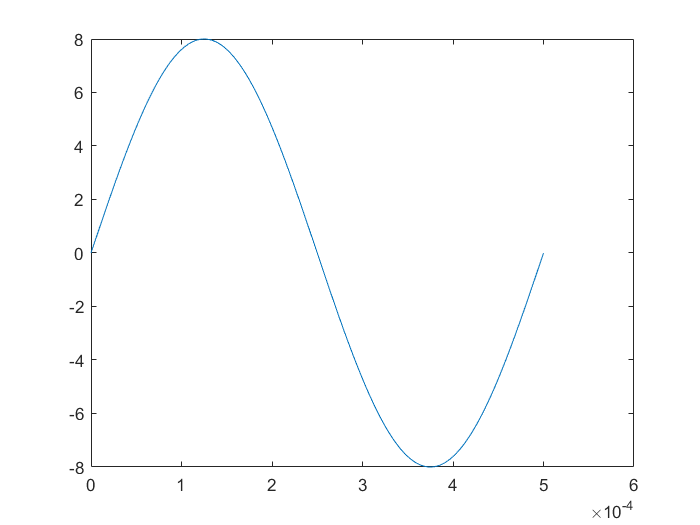

Error using matlab.graphics.axis.Axes/get
Operation terminated by user

Error in xlabel (line 56)
    h = get(ax,'XLabel');

figure()
t = 0:Ts:Tb;
plot(t, signal1(A, Tb, t));
xlabel('Time (second)')

ylabel('Signal waveform (Volt)')

#### Section 02

Sinusoid:

figure()
t = 0:Ts:4*Tb;
plot(t, signal1(A, Tb, t));


Half wave sinusoid:

figure()
t = 0:Ts:4*Tb;
plot(t, signal2(A, Tb, t));

Non-linear sinusoid:

figure()
t = 0:Ts:1*Tb;
plot(t, signal3(A, Tb, t)); ylim([-A-1, A+1]);

Pulse:

figure();
t = 0:Ts:6*Tb;
plot(t, signal4(A, Tb, t));
ylim([-A-1, A+1]);

Triangle wave:

figure();
t = 0:Ts:5*Tb;
plot(t, signal5(A, Tb, t));
ylim([-A-1, A+1]);

Task2:

figure();
t = 0:Ts:2*Tb;
plot(t, signal6(A, Tb, t));
ylim([-A-1, A+1]);

#### Section 03

Fourier Series:


$$f\left(t\right)=\frac{1}{2}a_0 +\sum_{n=1}^{\infty } a_n \cos \left(\frac{2\pi n}{T}t\right)+b_n \sin \left(\frac{2\pi n}{T}t\right)$$


Fourier Series Coefficients:


$$a_n =\frac{2}{T}\int_0^T f\left(t\right)\cos \left(\frac{2\pi n}{T}t\right)\textrm{dt}$$
                        
$$b_n =\frac{2}{T}\int_0^T f\left(t\right)\sin \left(\frac{2\pi n}{T}t\right)\textrm{dt}$$


Complex Fourier Coefficients:


$$X_n =\frac{1}{T\;}\int_0^T \;f\left(t\right)e^{-j\frac{\;2\pi \textrm{nt}\;}{T}} \textrm{dt}$$


Relationship between Fourier Series Coefficient and Complex Fourier Coefficient:


$$X_n =\left\lbrace \begin{array}{cc}
\frac{1}{2}\left(a_n +{\textrm{jb}}_n \right) & n<0\\
\frac{1}{2}a_0  & n=0\\
\frac{1}{2}\left(a_n -{\textrm{jb}}_n \right) & n>0
\end{array}\right.$$
                   
$$\Rightarrow \;\left|X_n \right|=\sqrt{\left(a_n^2 +b_n^2 \right)}$$


signal = @(t) signal5(A, Tb, t);

an = @(n) (2/Tb) * integral(@(t) signal(t) .* cos(2*pi.*n.*rb.*t), 0, Tb);
bn = @(n) (2/Tb) * integral(@(t) signal(t) .* sin(2*pi.*n.*rb.*t), 0, Tb);

Xn = zeros(21, 2);
for n = 0:20
    Xn(n+1, :) = [n, sqrt(an(n).^2 + bn(n).^2)];
end
Xn

#### Section 04

Reconstruction and Gibbs phenomenon

figure()
num_harmonics = 20;
t = 0:Ts:Tb;
rec_signal = reconstruct(an, bn, rb, num_harmonics, t);
subplot(1, 2, 1); plot(t, signal(t)); ylim([min(signal(t))-1, max(signal(t))+1]);
subplot(1, 2, 2); plot(t, rec_signal); ylim([min(rec_signal)-1, max(rec_signal)+1]);

Mean Square Error (MSE) of Reconstruction:

rec_error = mean((signal(t) - rec_signal) .^ 2)

#### Section 05

The spectrum estimation is done by SpectrumAnalyser tool in DSP toolbox.

signal = @(t) signal5(A, Tb, t);
t2 = (0:Ts:(10*Tb))';
scope = dsp.SpectrumAnalyzer();
scope.SampleRate = fs;

scope.PlotAsTwoSidedSpectrum = false;
scope.SpectrumUnits = "Watts";
scope.PeakFinder.Enable = true;
scope.PeakFinder.NumPeaks = 21;
scope(signal(t2));
release(scope);

The peaks of spectrum analyser are $x_n$ and have the following relationship with $X_n$:


$$X_0 =2\sqrt{\;x_0 }$$
                    
$$X_n =2\sqrt{\;\frac{x_n }{2}}=\sqrt{\;2x_n }$$


### Functions Definition

Simple sinusoid:

function s = signal1(A, T, t)
    t = mod(t, T);
    s = A * sin(2 .* pi .* t / T);
end

Half wave sinusoid:

function s = signal2(A, T, t)
    t = mod(t, T);
    s = A * sin(2 .* pi .* t / T);
    s(t > T/2) = -A;
end

Non-linear sinusoid:

function s = signal3(A, T, t)
    t = mod(t, T);
    s = A * sin(2 .* pi .* t ./ T);
    s((s > -A/2) & (s < A/2)) = 0;
end

Pulse:

function s = signal4(A, T, t)
    t = mod(t, T);
    s = 0 .* t;
    s(t <= T/2) = A;
    s(t > T/2 ) = -A;
end

Triangle Wave:

Note: How the lines equations have been found?

function s = signal5(A, T, t)
    t = mod(t, T);
    s = 0 .* t;
    s(t <= T/2) = A;    %Pulse on positive cycle
    s((t > T/2)&(t<3*T/4)) = -4 * A / T * (t((T/2 < t) & (t < 3*T/4)) - T/2); %First half of Negative Triangle cycle
    s(3*T/4 <= t ) = 4 * A / T * (t(3*T/4 <= t ) - T); %Second half of Negative Triangle cycle
    
end

Task 2:

function s = signal6(A, T, t)
    t = mod(t, T);
    s = 0 .* t;
    s(t <= T/2) = A;    %Pulse on positive cycle
    s((t > T/2)&(t<3*T/4)) = -4 * A / T * (t((T/2 < t) & (t < 3*T/4)) - T/2); %First half of Negative Triangle cycle
    s(3*T/4 <= t ) = 4 * A / T * (t(3*T/4 <= t ) - T); %Second half of Negative Triangle cycle
    
end

Reconstruction:

function s = reconstruct(an, bn, f, n, t)
    s = 0.5 * an(0);
    for nc = 1:(n-1)
        s = s + an(nc) * cos(2 * pi * f .* nc .* t) + bn(nc) * sin(2 * pi * f .* nc .* t);
    end
end